# Example

Computation of the eigenfrequencies and mode shapes of a beam with different boundary conditions. Axis orientation: The beam has a main axis z, and its cross-section is symmetric to axis x and y

## Definition of the geometry

clearvars;close all;clc;
geometry.L = 100; % beam length (m)
geometry.E = 2.1e11; % Young Modulus (Pa)
geometry.nu = 0.3; % Poisson ratio
geometry.rho = 7850; % density (kg/m^3)

% case of a cylinder
% D = geometry.L/20; % beam diameter (m)  
% --> beam is symmetrical around axes y and z
% Iy = pi.*D.^4./64;
% Ix = pi.*D.^4./64;
% geometry.I = Iy; % affectation of quadratic moment
% number of discretisation points for the beam
% geometry.y = linspace(0,geometry.L ,100); 
% V = pi.*D.^2*geometry.L;
% geometry.m = geometry.rho.*V./geometry.L;

% Rectangular beam
B = geometry.L/100;
H = geometry.L/100;
Iy = B*H.^3/12; % quadratic moment
Ix = H*B.^3/12; % quadratic moment
geometry.I = Iy; % affectation of quadratic moment
% number of discretisation points for the beam
geometry.y = linspace(0,geometry.L ,100);
V = B*H*geometry.L;
geometry.m = geometry.rho.*V./geometry.L; % in kg/m

% Number of modes
Nmodes =4; % number of mode wanted

## Case 1: pinned-pinned

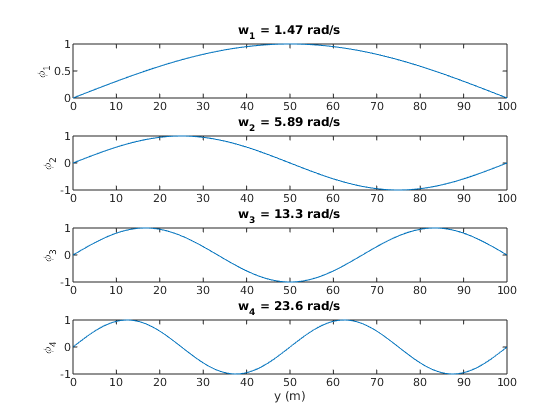

BC = 1; % pinned-pinned
[phi,wn] = eigenModes(geometry,BC,Nmodes);

figure
for ii=1:Nmodes,
    subplot(Nmodes,1,ii)
    box on;grid on
    plot(geometry.y,phi(ii,:));
    ylabel(['\phi_',num2str(ii)])
    title(['w_',num2str(ii),' = ',num2str(wn(ii),3),' rad/s']); 
end
set(gcf,'color','w')
xlabel('y (m)');

## Case 2: clamped-free 

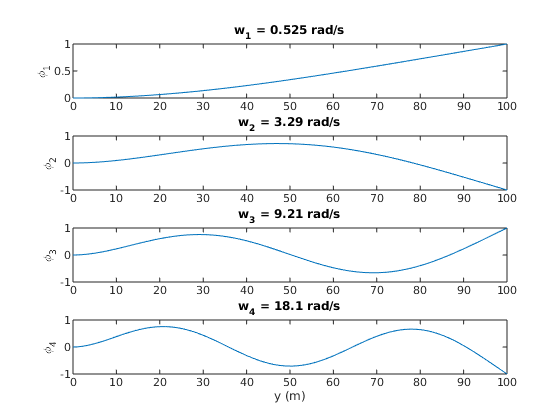

BC = 2;% clamped-free
[phi,wn] = eigenModes(geometry,BC,Nmodes);

figure
for ii=1:Nmodes,
    subplot(Nmodes,1,ii)
    box on;grid on
    plot(geometry.y,phi(ii,:));
    ylabel(['\phi_',num2str(ii)])
    title(['w_',num2str(ii),' = ',num2str(wn(ii),3),' rad/s']); 
end
set(gcf,'color','w')
xlabel('y (m)');

## Case 3: clamped-clamped

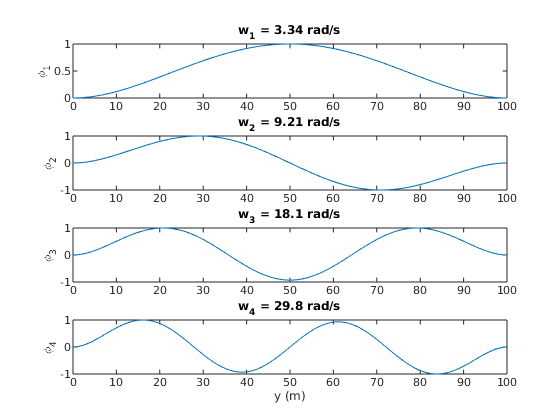

BC = 3; % clamped-clamped
[phi,wn] = eigenModes(geometry,BC,Nmodes);

figure
for ii=1:Nmodes,
    subplot(Nmodes,1,ii)
    box on;grid on
    plot(geometry.y,phi(ii,:));
    ylabel(['\phi_',num2str(ii)])
    title(['w_',num2str(ii),' = ',num2str(wn(ii),3),' rad/s']); 
end
set(gcf,'color','w')
xlabel('y (m)');

## Case 4: clamped-pinned

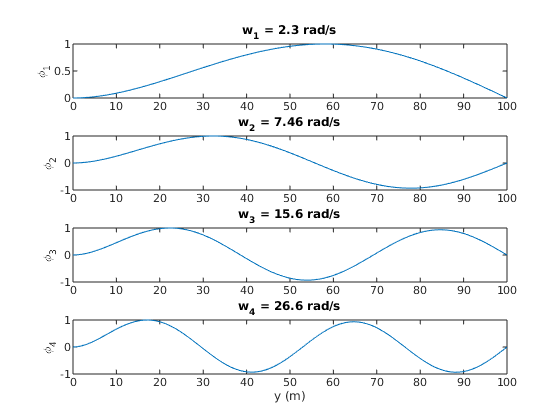

BC = 4;% clamped-pinned
[phi,wn] = eigenModes(geometry,BC,Nmodes);

figure
for ii=1:Nmodes,
    subplot(Nmodes,1,ii)
    box on;grid on
    plot(geometry.y,phi(ii,:));
    ylabel(['\phi_',num2str(ii)])
    title(['w_',num2str(ii),' = ',num2str(wn(ii),3),' rad/s']); 
end
set(gcf,'color','w')
xlabel('y (m)');